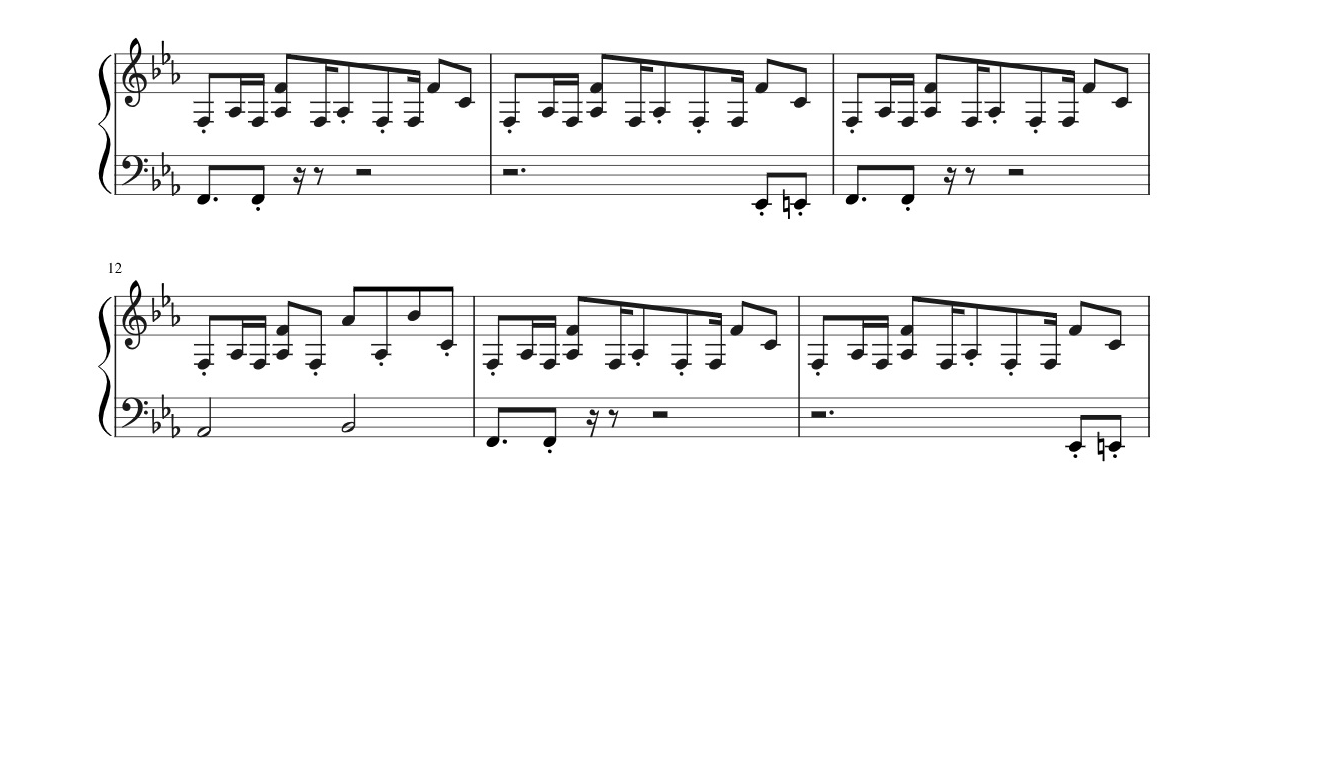



image = loadimage('D:\Skola\ABoB\TNM034-OMR\Images\TestStaff.jpg');
imshow(image)

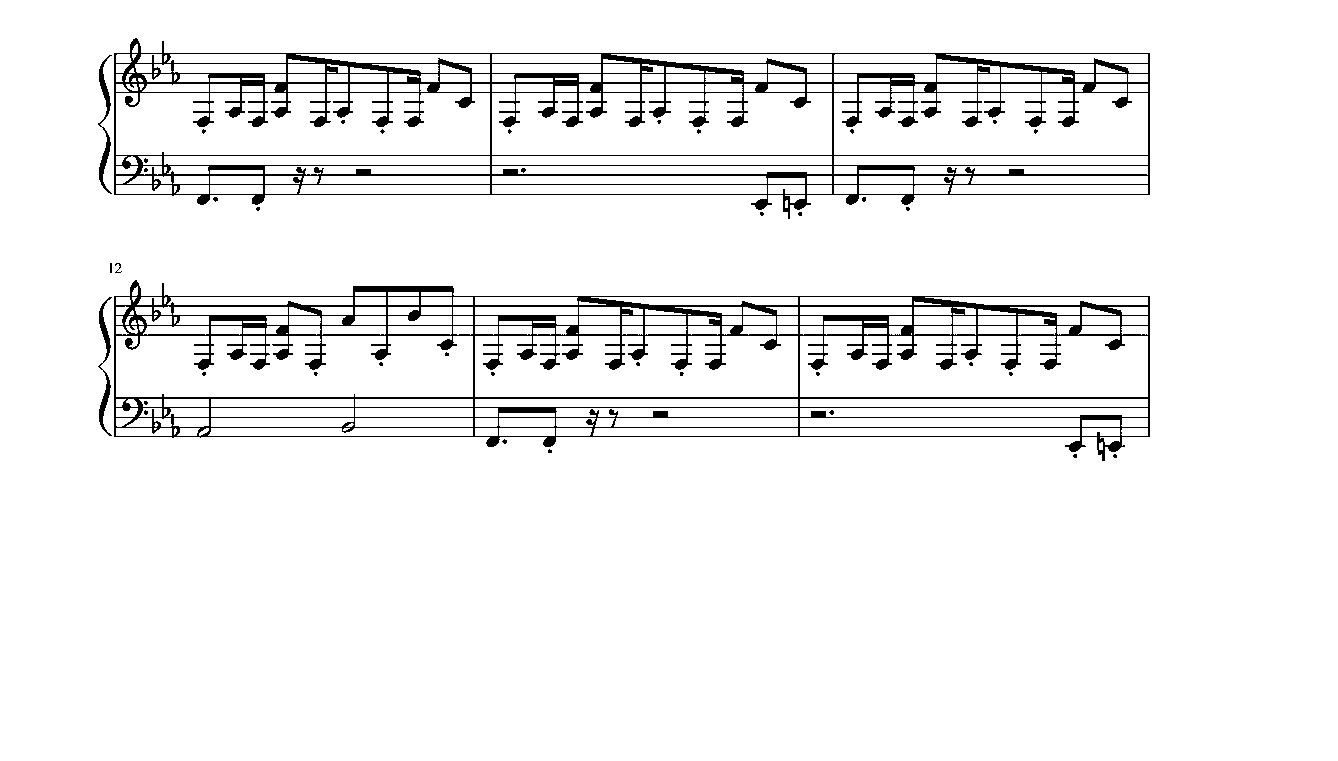


binaryImage = im2bw(image,0.7);
imshow(binaryImage)

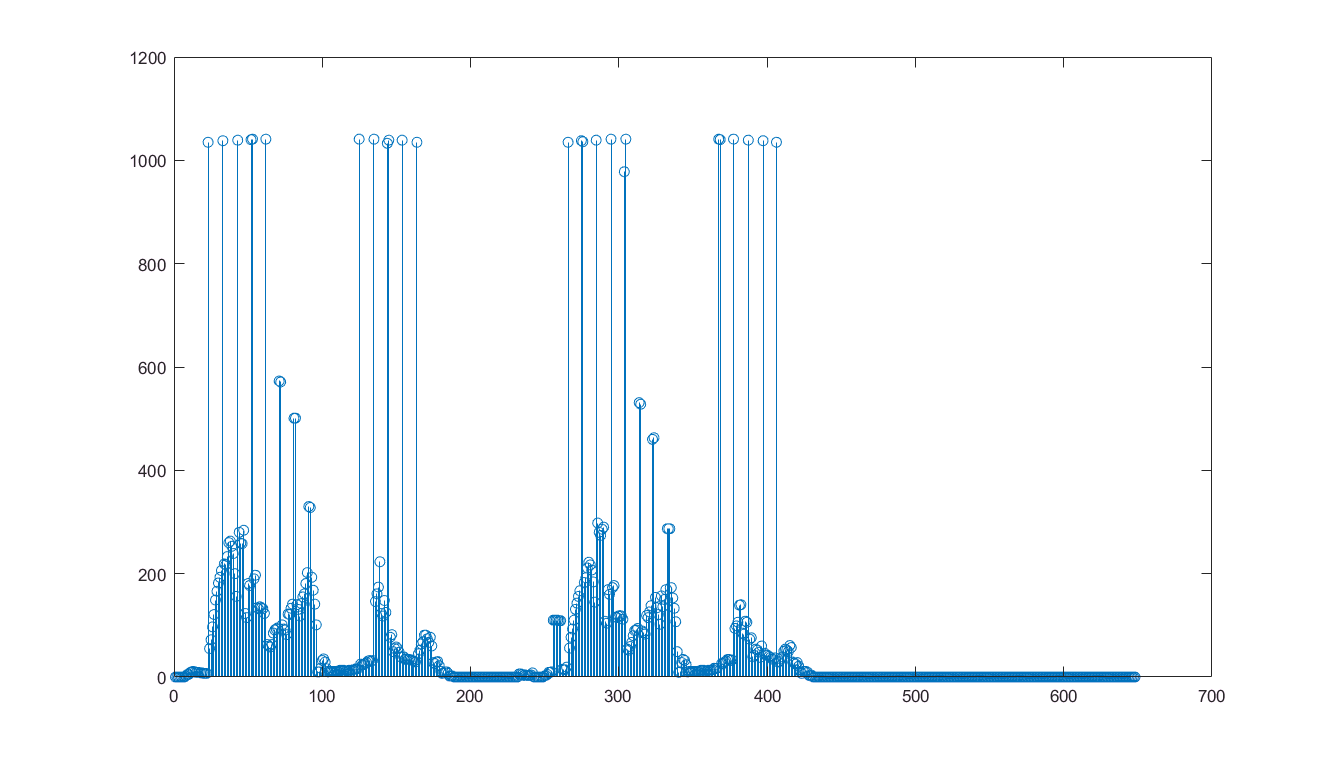


verticalProfile = sum(binaryImage, 2);
[rows, columns] = size(binaryImage);
stem(columns-verticalProfile)
hold off

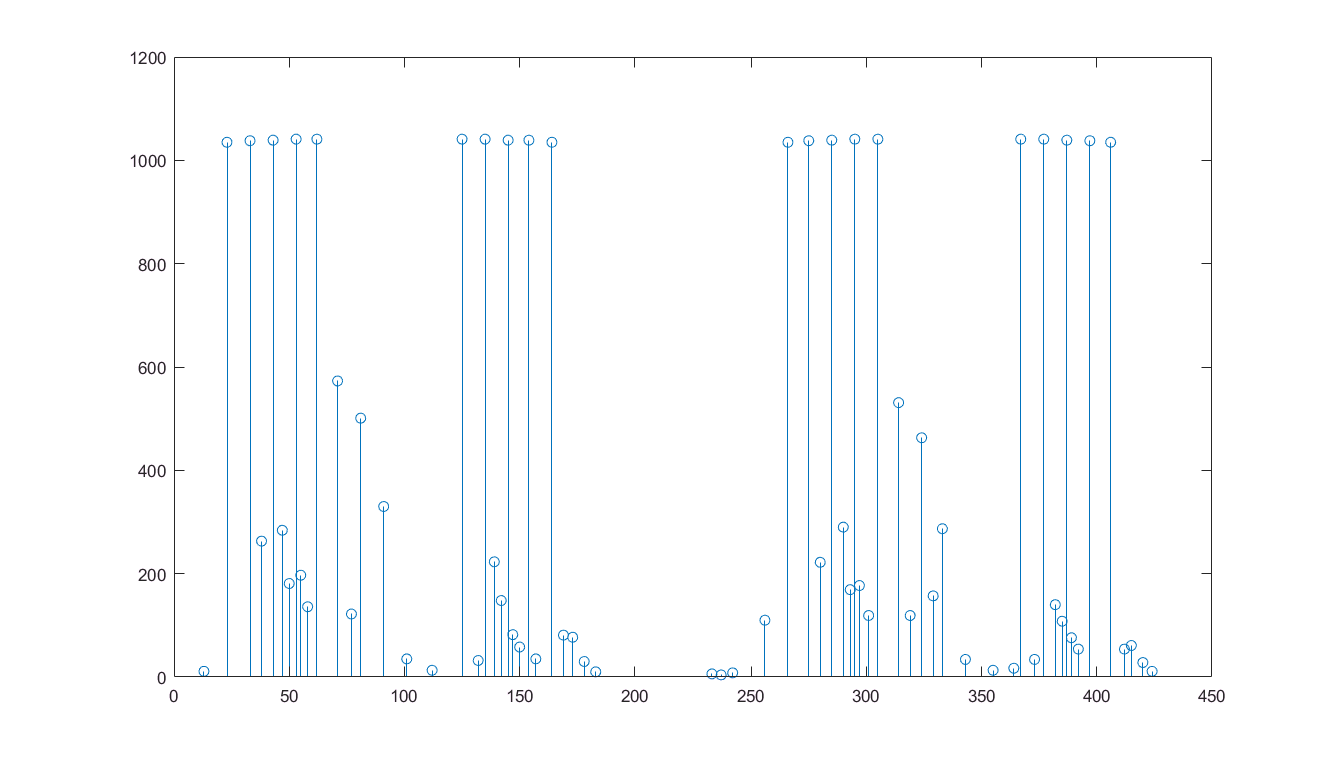



imageVector = im2double(verticalProfile);
[pks,locs] = findpeaks((columns-imageVector)); 
stem(locs,pks);



maxValue_Peaks = max(pks);
staffs = pks .* (pks > maxValue_Peaks*0.9);
hold off 

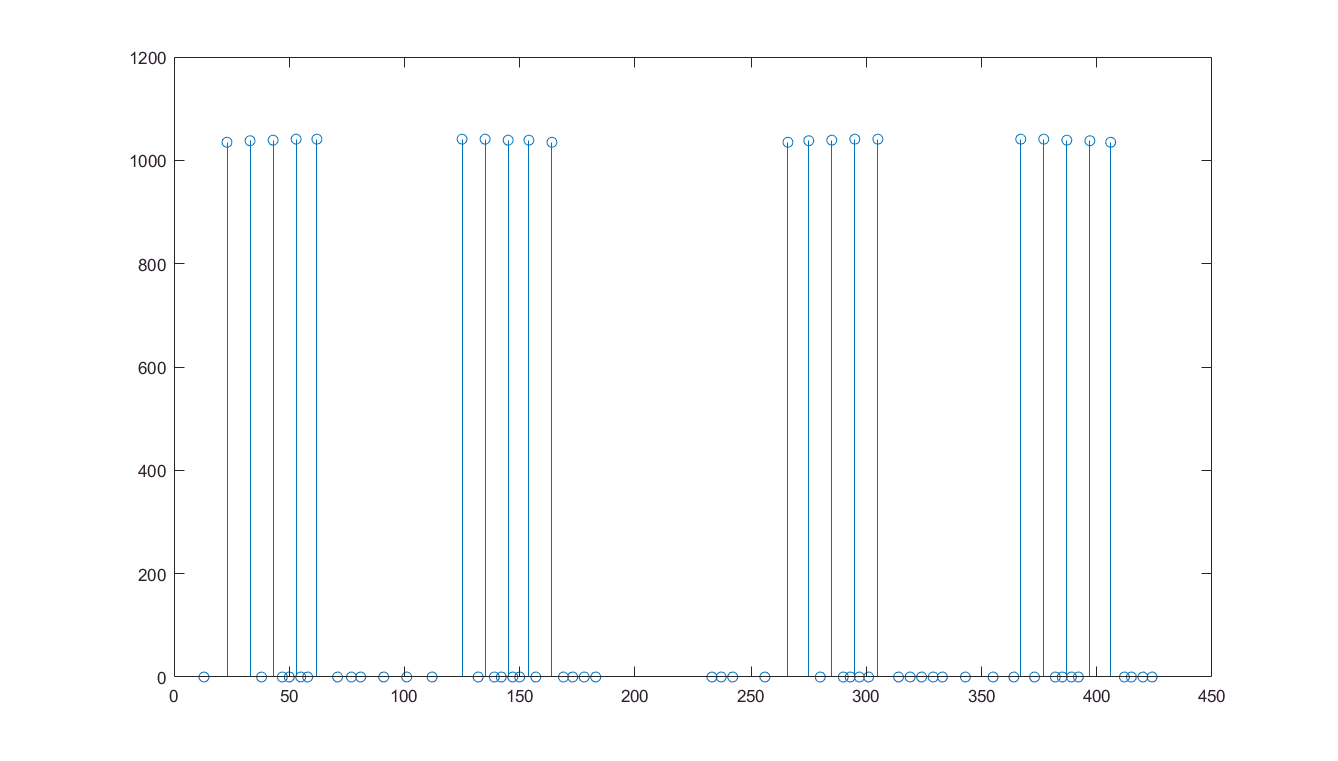

stem(locs,staffs)

%create an array containing the rows where the stafflines are located (staffRows)
j = locs(:) < staffs(:);
staffRows = j.*locs;
staffRows(staffRows==0) = [];  


a  = [];
position = 1;
for p = 1:(length(staffRows)-1)
   a = staffRows(position+1)-staffRows(position);
    if(mod(p,4) == 0)
        position = position+2; 
    end
end 

StaffDistance = staffRows(2)-staffRows(1);